## Calculate the R2 Value for each combination of signals

warning('off','all')
correlatedSignalMatrix = cell(numOfSignals, numOfSignals);
correlatedSignalMatrix2 = cell(numOfSignals, numOfSignals);
for i = 1:numOfSignals
    for j = i:numOfSignals
        if i ~= j
            str = "";
            for k = 1:numOfFeatures_Freq
                sig1 = FeatureTable1.(signalName(i) + featureNames_Freq(k));
                sig2 = FeatureTable1.(signalName(j) + featureNames_Freq(k));
    
                mdl = fitlm(sig1, sig2);
                R2 = mdl.Rsquared.Ordinary;

                %if R2 > 0.9 && R2 < 1
                if R2 > 0.3 && R2 < 0.5
                    str = str + sprintf('%i %s %3g \n', k, featureNames_Freq(k), round(R2, 3));  
                    correlatedSignalMatrix{i, j} = [correlatedSignalMatrix{i, j} k];
                end
                correlatedSignalMatrix2{i, j} = [correlatedSignalMatrix2{i, j} R2];
            end
            if (str ~= "")
                disp( sensorNames(i) + " " + sensorNames(j) );
                disp(str)
            end
        end
    end
end

21:07 Angle over Rolls (degrees) 21:17 Angle under roll (degrees)


2 PeakAmp1 0.368 



21:07 Angle over Rolls (degrees) 21:36 Actual force (KN)


2 PeakAmp1 0.389 
3 PeakFreq1 0.442 



21:10 Position over Rolls (mm) 21:36 Actual force (KN)


3 PeakFreq1 0.431 



21:12 Actual moment over Rolls (Nm) 31:32 Height position (?)


1 BandPower 0.34 



21:12 Actual moment over Rolls (Nm) 21:36 Actual force (KN)


2 PeakAmp1 0.369 



21:17 Angle under roll (degrees) 31:32 Height position (?)


2 PeakAmp1 0.306 



21:20 Actual moment under Rolls (Nm) 31:32 Height position (?)


1 BandPower 0.313 



21:20 Actual moment under Rolls (Nm) 21:36 Actual force (KN)


2 PeakAmp1 0.48 



21:31 Width position (mm) 31:32 Height position (?)


2 PeakAmp1 0.423 



21:31 Width position (mm) 21:33 Error position for height (?)


1 BandPower 0.358 



21:31 Width position (mm) 21:34 Error position for the width (?)


1 BandPower 0.332 



21:31 Width position (mm) 21:35 Set point force (KN)


3 PeakFreq1 0.404 



31:32 Height position (?) 21:34 Error position for the width (?)


2 PeakAmp1 0.427 



21:34 Error position for the width (?) 21:35 Set point force (KN)


3 PeakFreq1 0.473 



## Plot signals that have R2 above threshold

Signal 1:Signal 4 - Features: 1

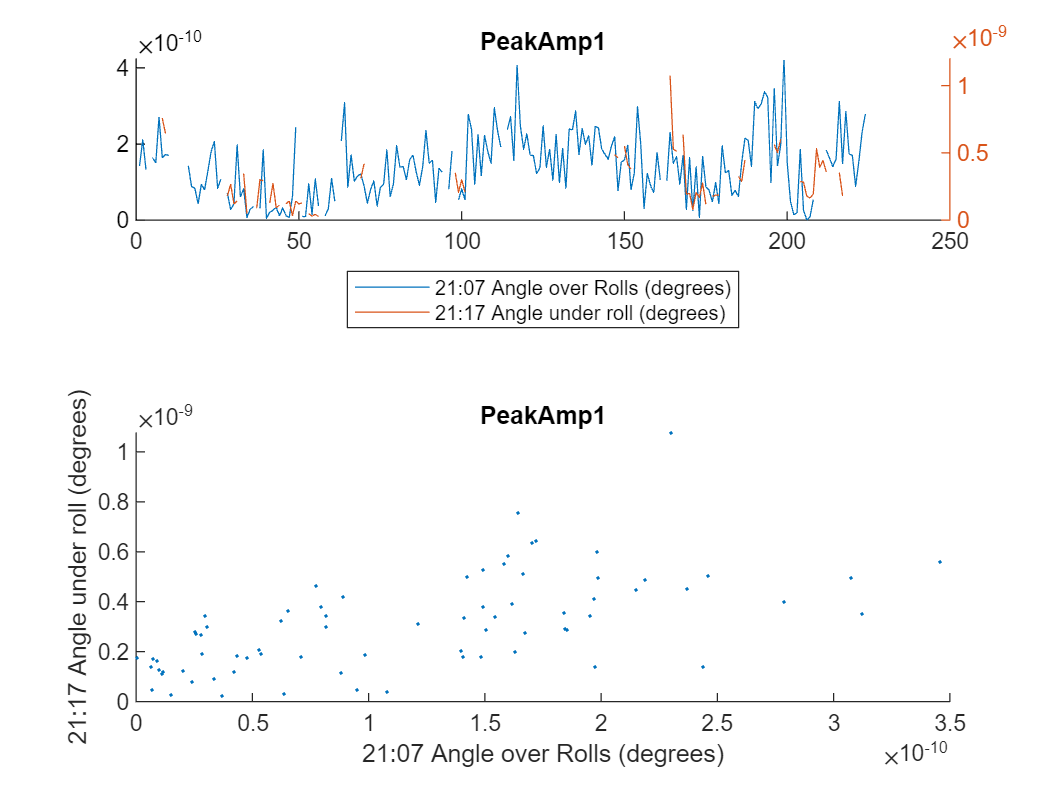

Signal 1:Signal 12 - Features: 2

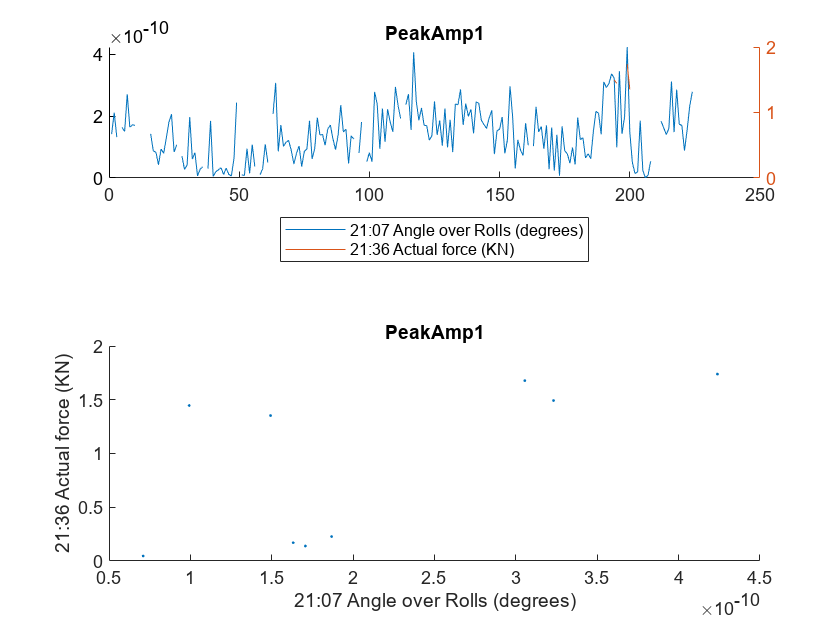

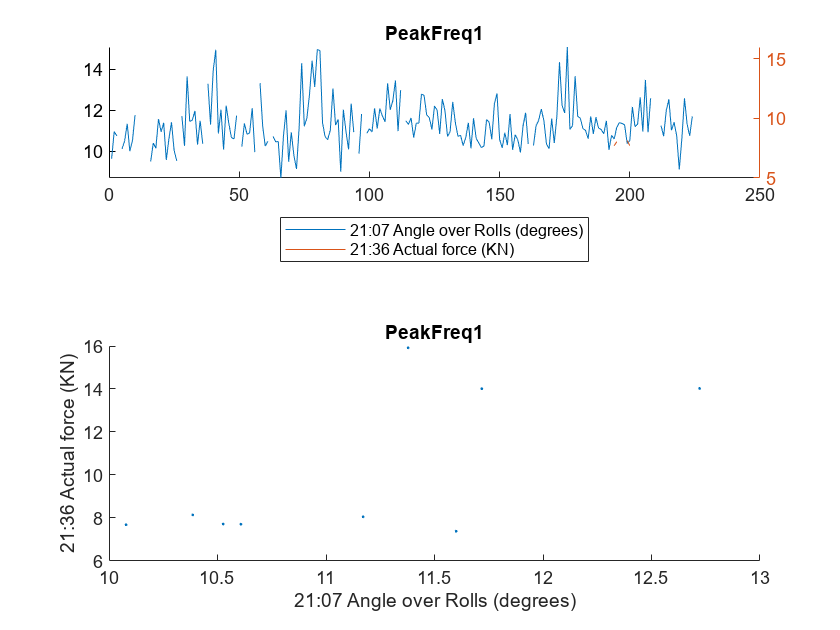

Signal 2:Signal 12 - Features: 1

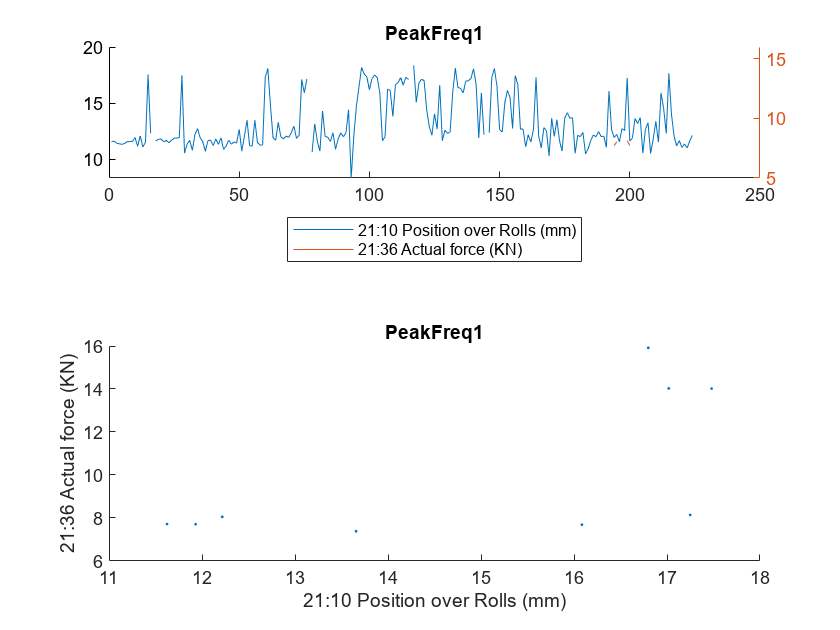

Signal 3:Signal 8 - Features: 1

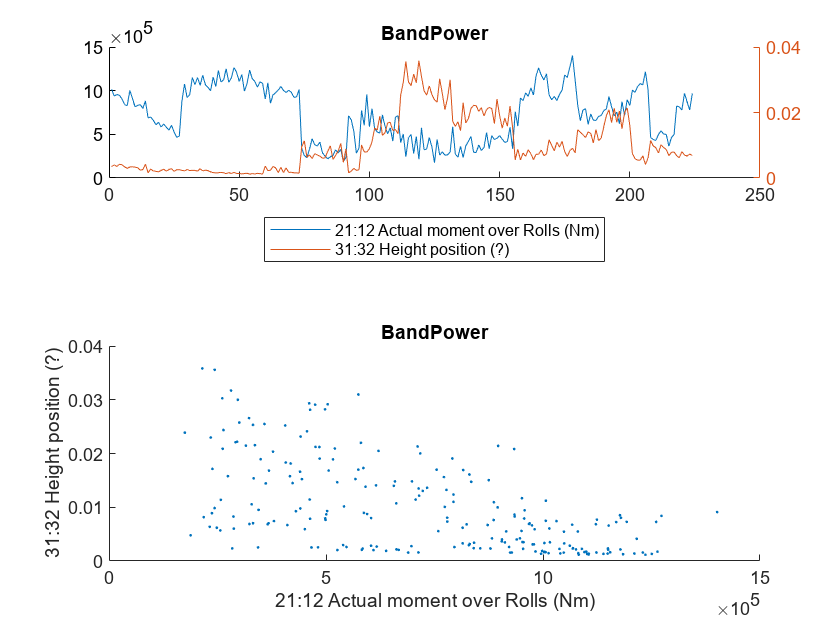

Signal 3:Signal 12 - Features: 1

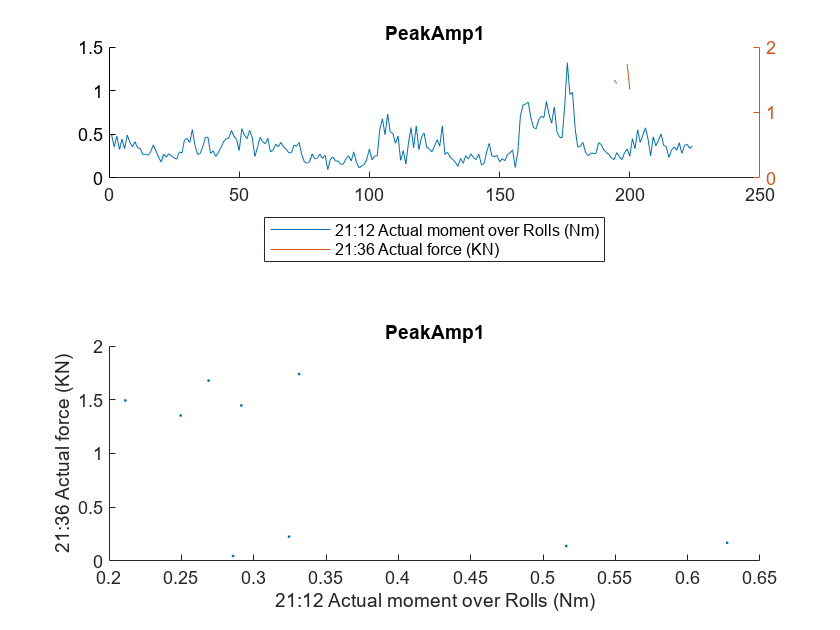

Signal 4:Signal 8 - Features: 1

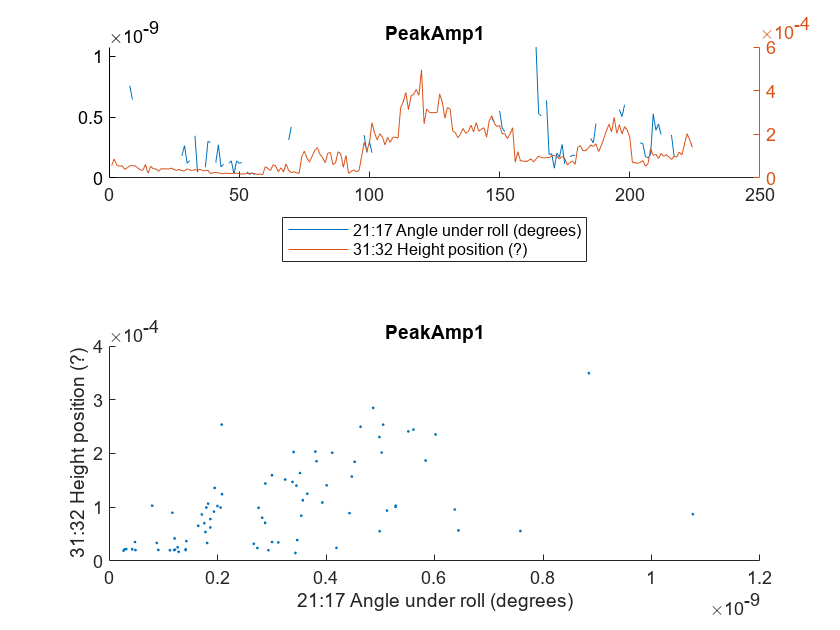

Signal 5:Signal 8 - Features: 1

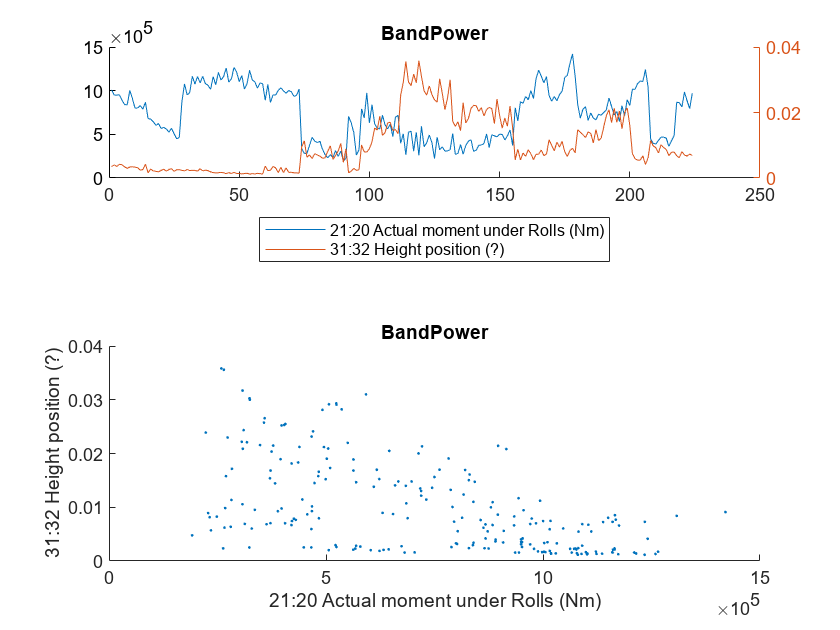

Signal 5:Signal 12 - Features: 1

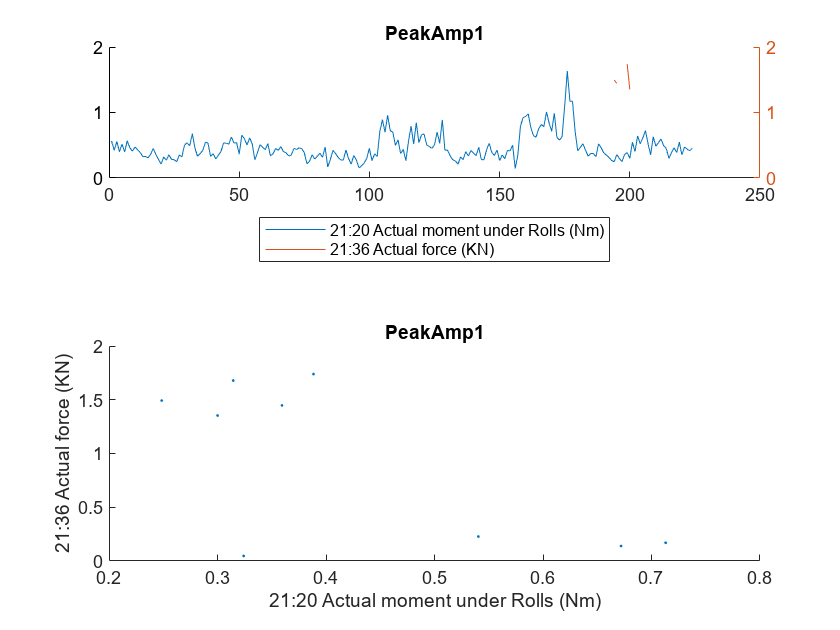

Signal 7:Signal 8 - Features: 1

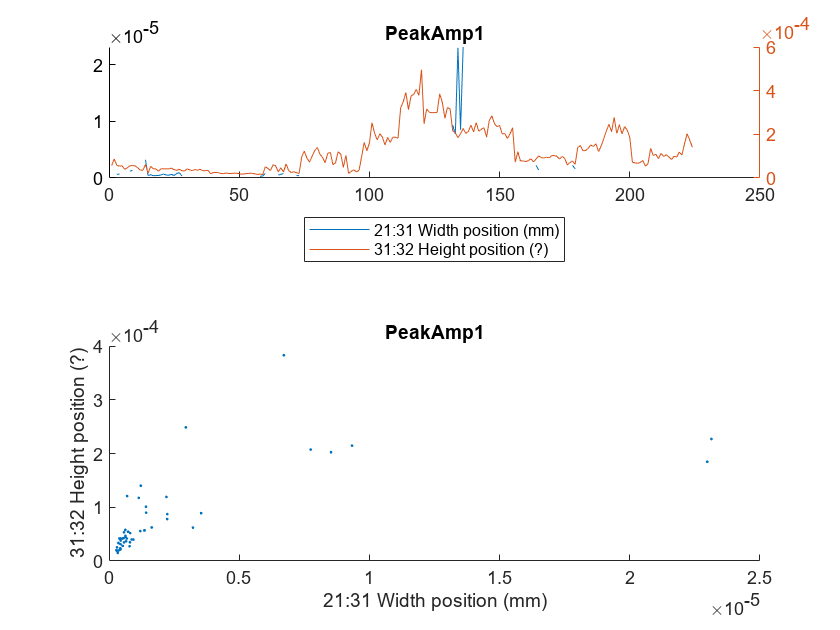

Signal 7:Signal 9 - Features: 1

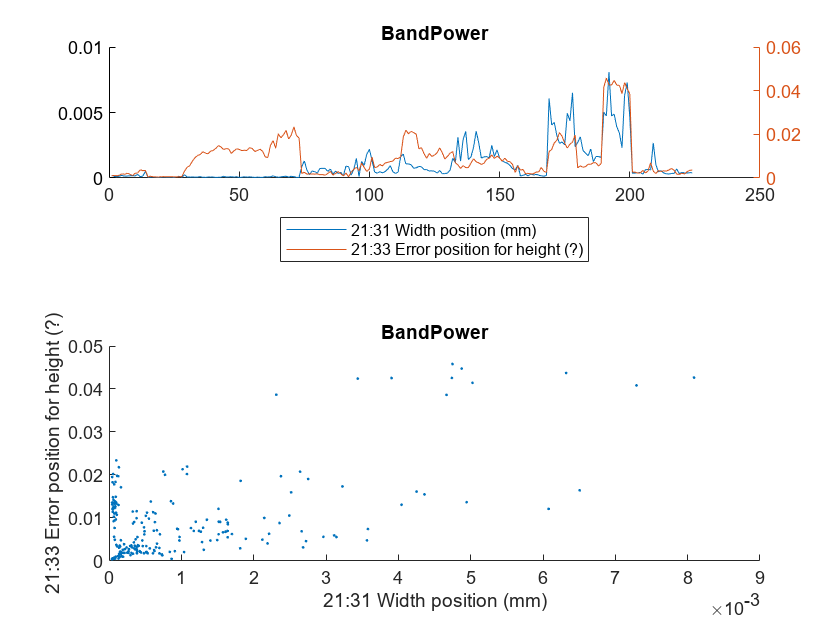

Signal 7:Signal 10 - Features: 1

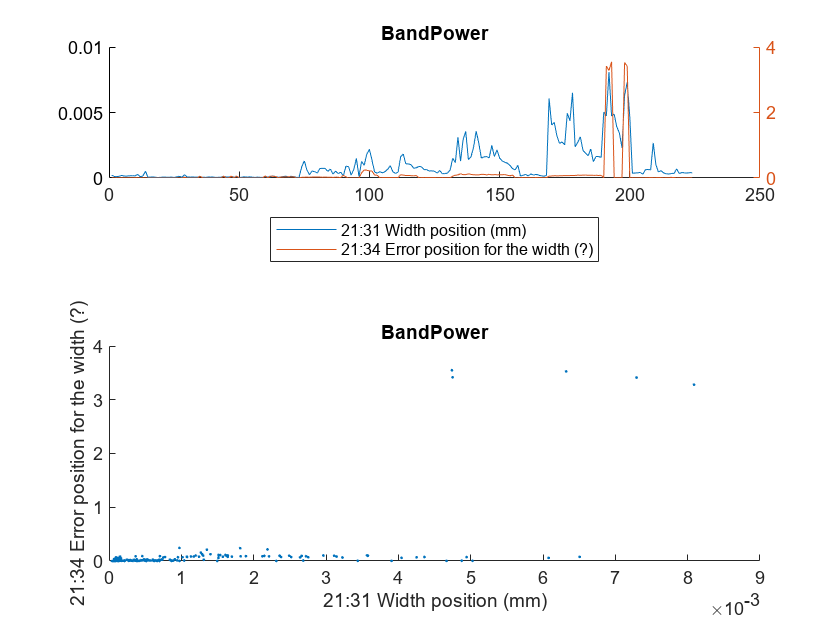

Signal 7:Signal 11 - Features: 1

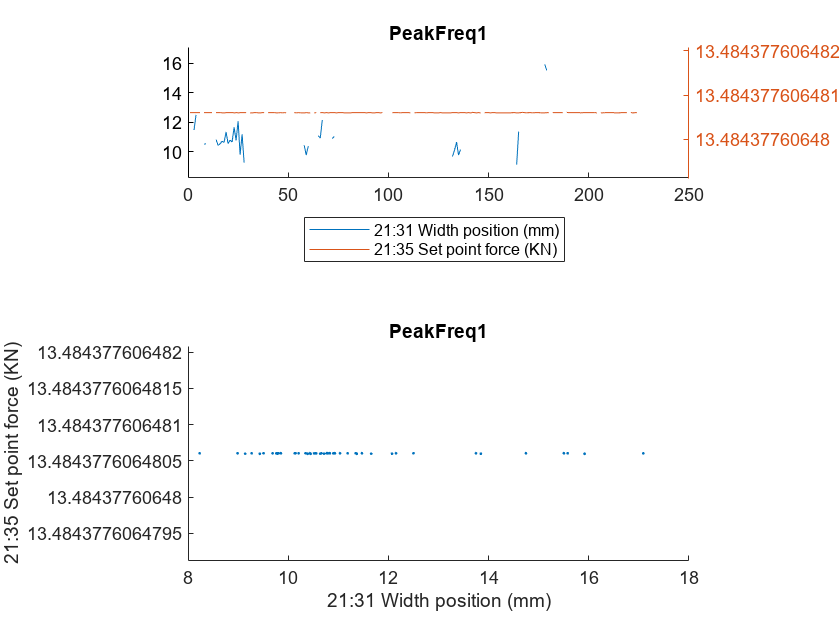

Signal 8:Signal 10 - Features: 1

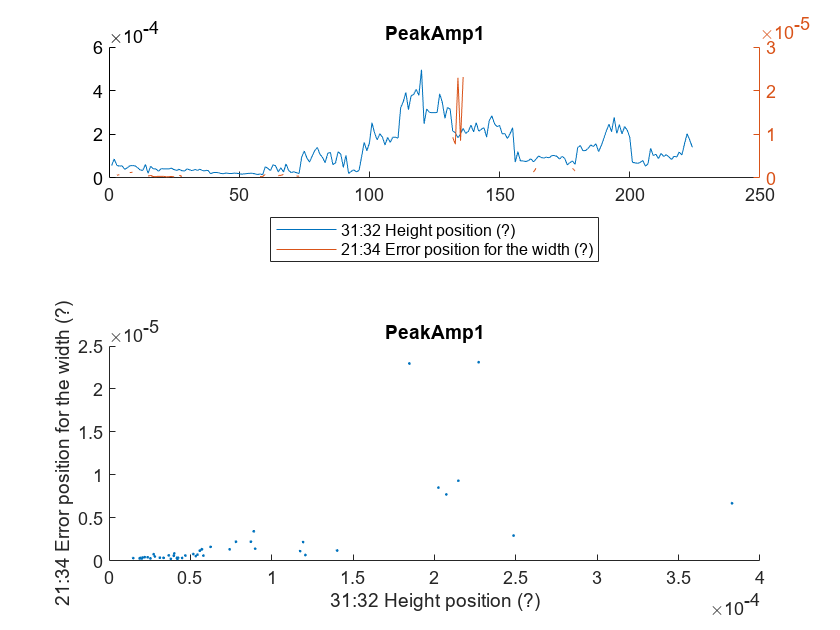

Signal 10:Signal 11 - Features: 1

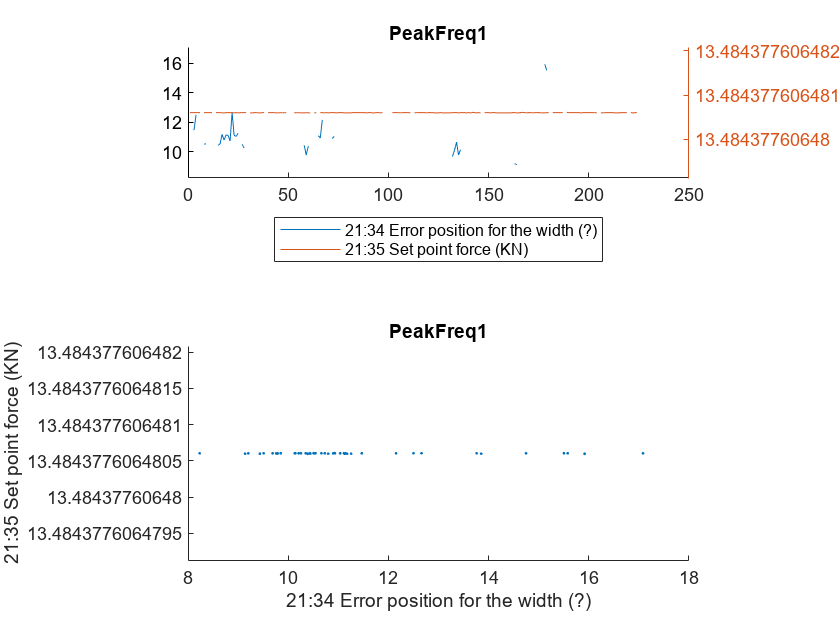

for i=1:numOfSignals
    for j=1:numOfSignals
        if (size(correlatedSignalMatrix{i,j}, 2))
            fprintf("Signal %i:Signal %i - Features: %i", i, j, size(correlatedSignalMatrix{i,j}, 2));
            plotCorrelatedSignals(i, j, correlatedSignalMatrix{i,j}, sensorNames, featureNames_Freq, signalName, FeatureTable1)
        end
    end
end

## Function to plot two signals in time domain

function [] = plotCorrelatedSignals(signalNum1, signalNum2, correlatedFeatures, sensorNames, featureNames, signalName, FeatureTable1)
    for i=1:size(correlatedFeatures, 2)
        figure(); 
        subplot(2, 1, 1); hold on;
        feature = featureNames(correlatedFeatures(i));
        plot(FeatureTable1.(signalName(signalNum1) + feature));
        yyaxis right;
        plot(FeatureTable1.(signalName(signalNum2) + feature));
        legend(sensorNames(signalNum1), sensorNames(signalNum2), "Location", 'southoutside');
        title(feature);

        subplot(2, 1, 2); 
        feature = featureNames(correlatedFeatures(i));
        scatter(FeatureTable1.(signalName(signalNum1) + feature), FeatureTable1.(signalName(signalNum2) + feature), 2, 'filled');
        xlabel(sensorNames(signalNum1))
        ylabel(sensorNames(signalNum2));
        title(feature);
    end
end